# Cleaning Workspace

clear;
close all;
clc;

# Plot Parameters

linewidth  = 2;
markersize = 10;
fontsize   = 20;
fontname   = 'Times New Roman';

bas_size = 0.8;

legend_algo = {'ESSEP','ESSMMF','SOS','FRBS'};
legend_pa   = {'EPA','MMFPA'};

cat_1 = categorical(legend_algo);
cat_1 = reordercats(cat_1,legend_algo);

color = [0.0000 0.4470 0.7410;
         0.8500 0.3250 0.0980;
         0.9290 0.6940 0.1250;
         0.4940 0.1840 0.5560;
         0.4660 0.6740 0.1880;
         0.3010 0.7450 0.9330;
         0.6350 0.0780 0.1840;
         0.5423 0.8950 0.0042;
         0.0430 0.8973 0.2345;
         0.7843 0.7725 0.7176]; % lite gray

marker = {'o','s','v','^','>','<','d','+','x'};

addpath('./functions/')

M = 50;                                                             % Number of antennas at the base station
K = 25;                                                             % Number of users at the cell
L = 1;                                                             % Number of selected users

N_ALG = 4;
N_PRE = 2;

channel_type = 'ur-los';

R = 500;                                                             % Cell's raidus (circumradius) in meters
r = sqrt(3)/2*R;                                                     % Cell's inradius in meters

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

commcell.nAntennas       = M;                                        % Number of Antennas
commcell.nUsers          = K;                                        % Number of Users
commcell.radius          = R;                                        % Cell's raidus (circumradius) in meters
commcell.bsHeight        = 32;                                       % Height of base station in meters
commcell.userHeight      = [1 2];                                    % Height of user terminals in meters ([min max])
commcell.nPaths          = 30;                                       % Number of Multipaths
commcell.frequency       = 1.9e9;                                    % Carrier frequency in Hz
commcell.meanShadowFad   = 0;                                        % Shadow fading mean in dB
commcell.stdDevShadowFad = 8;                                        % Shadow fading standard deviation in dB
commcell.city            = 'large';                                  % Type of city

linkprop.bsPower         = 10;                                       % in Watts
linkprop.userPower       = 0.2;                                      % in Watts
linkprop.AntennaGainBS   = 0;                                        % in dBi
linkprop.AntennaGainUser = 0;                                        % in dBi
linkprop.noiseFigureBS   = 9;                                        % in dB
linkprop.noiseFigureUser = 9 ;                                       % in dB
linkprop.bandwidth       = 20e6;                                     % in Hz

[~,snr_db] = linkBudgetCalculation(linkprop);                        % SNR in dB
snr        = 10^((snr_db)/10);                                       % SNR

[H,beta,user_pos] = massiveMIMOChannel(commcell,channel_type);

algorithm_type = {'exhaustive search selection ep', ...
                  'exhaustive search selection mmf', ...
                  'semi-orthogonal selection', ...
                  'fr-based selection'};


# Initialization

se_epa           = zeros(K,N_PRE);
se_mmfpa         = zeros(K,N_PRE);

se_epa_sel       = zeros(L,N_PRE,N_ALG);
se_mmfpa_sel     = zeros(L,N_PRE,N_ALG);

sum_se_epa_sel   = zeros(N_PRE,N_ALG);
sum_se_mmfpa_sel = zeros(N_PRE,N_ALG);

min_se_epa_sel   = zeros(N_PRE,N_ALG);
min_se_mmfpa_sel = zeros(N_PRE,N_ALG);

eta     = zeros(K,N_PRE);
eta_sel = zeros(L,N_PRE);

S_set = zeros(L,N_PRE,N_ALG);

# Users distribution across the cell

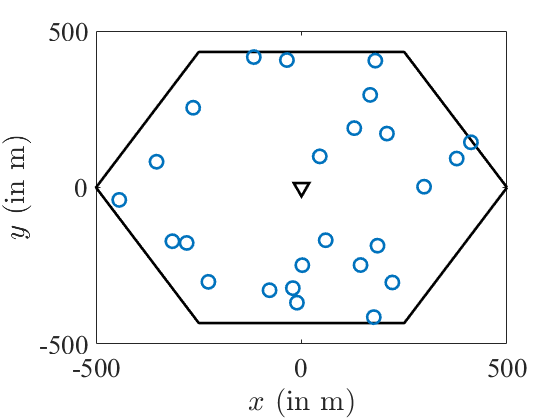

figure;

plot(x_cell,y_cell,'k','linewidth',linewidth);
hold on;
plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
plot(user_pos(:,1), user_pos(:,2),'o','color',color(1,:),'linewidth',linewidth,'markersize',markersize);

xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-R R]);
ylim([-R R]);

% No Selection

[~,eta(:,1)] = maxMinFairness(H,beta,snr,'algorithm 2');

eta(:,2) = (1/sum(1./beta))./beta;

[se_epa(:,1),se_epa(:,2)]     = DLspectralEfficiency(H,beta,snr,1/K);
[se_mmfpa(:,1),se_mmfpa(:,2)] = DLspectralEfficiency(H,beta,snr,eta);

sum_se_epa = sum(se_epa,1);
min_se_epa = min(se_epa,[],1);

sum_se_mmfpa = sum(se_mmfpa);
min_se_mmfpa = min(se_mmfpa,[],1);

for alg_idx = 1:N_ALG    
    [H_s,S_aux] = userSelector(H,beta,snr,algorithm_type{alg_idx},'fixed',L,[]);
    
    if alg_idx == 1
        H_aux = H_s(:,:,1);
        S_set(:,:,alg_idx) = S_aux(:,1:2);
    elseif alg_idx == 2
        H_aux = H_s(:,:,1);
        S_set(:,:,alg_idx) = S_aux;
    else
        H_aux = H_s;
        S_set(:,:,alg_idx) = repmat(S_aux,1,N_PRE);
    end
    
    [~,eta_sel(:,1)] = maxMinFairness(H_aux,beta(S_set(:,1,alg_idx)),snr,'algorithm 2');
    
    eta_sel(:,2) = (1/sum(1./beta(S_set(:,2,alg_idx))))./beta(S_set(:,2,alg_idx));
    
    [se_epa_sel(:,1,alg_idx),se_epa_sel(:,2,alg_idx)]     = DLspectralEfficiency(H_s,beta(S_set(:,:,alg_idx)),snr,1/L);
    [se_mmfpa_sel(:,1,alg_idx),se_mmfpa_sel(:,2,alg_idx)] = DLspectralEfficiency(H_s,beta(S_set(:,:,alg_idx)),snr,eta_sel);
    
    sum_se_epa_sel(:,alg_idx) = sum(se_epa_sel(:,:,alg_idx),1)';
    min_se_epa_sel(:,alg_idx) = min(se_epa_sel(:,:,alg_idx),[],1)';
    
    sum_se_mmfpa_sel(:,alg_idx) = sum(se_mmfpa_sel(:,:,alg_idx),1)';
    min_se_mmfpa_sel(:,alg_idx) = min(se_mmfpa_sel(:,:,alg_idx),[],1)';
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 2-by-1.

figure;

for alg_idx = 1:length(legend_algo)
    subplot(2,2,alg_idx);
    
    plot(x_cell,y_cell,'k','linewidth',linewidth);
    hold on;
    plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
    plot(user_pos(:,1), user_pos(:,2),marker{1},'color',color(10,:),'linewidth',linewidth,'markersize',markersize);
    plot(user_pos(S_set(:,1,alg_idx),1), user_pos(S_set(:,1,alg_idx),2),marker{1},'color',color(1,:),'linewidth',linewidth,'markersize',markersize);
    
    xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    
    title(legend_algo{alg_idx},'fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    
    set(gca,'fontname',fontname,'fontsize',fontsize);
    
    xlim([-R R]);
    ylim([-R R]);
end

figure;

for alg_idx = 1:length(legend_algo)
    subplot(2,2,alg_idx);
    
    plot(x_cell,y_cell,'k','linewidth',linewidth);
    hold on;
    plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
    plot(user_pos(:,1), user_pos(:,2),marker{1},'color',color(10,:),'linewidth',linewidth,'markersize',markersize);
    plot(user_pos(S_set(:,2,alg_idx),1), user_pos(S_set(:,2,alg_idx),2),marker{1},'color',color(2,:),'linewidth',linewidth,'markersize',markersize);
    
    xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    
    title(legend_algo{alg_idx},'fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    
    set(gca,'fontname',fontname,'fontsize',fontsize);
    
    xlim([-R R]);
    ylim([-R R]);
end
figure;

subplot(1,2,1);

bar(cat_1,10*[sum_se_epa_sel(1,:)' sum_se_mmfpa_sel(1,:)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Sum-throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize);

set(gca,'fontname',fontname,'fontsize',fontsize);

subplot(1,2,2);

bar(cat_1,10*[sum_se_epa_sel(2,:)' sum_se_mmfpa_sel(2,:)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Sum-throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize);

set(gca,'fontname',fontname,'fontsize',fontsize);

figure;

subplot(1,2,1);

bar(cat_1,10*[min_se_epa_sel(1,:)' min_se_mmfpa_sel(1,:)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Min throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize);

set(gca,'fontname',fontname,'fontsize',fontsize);
subplot(1,2,2);

bar(cat_1,10*[min_se_epa_sel(2,:)' min_se_mmfpa_sel(2,:)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Min throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize);

set(gca,'fontname',fontname,'fontsize',fontsize);